Script to look for constant velocity phases in test data and evaluate their detection.


%% Choose folders
listOfFolderNames =selector_multiFolder(pwd, 'Select trajectories to evaluate');
numFolders = length(listOfFolderNames);


%% Initialise preliminaries
mapfile = 'C:\Users\Alyssa\Documents\QuadStateEstimator\Resources\map_real';
map = load(fullfile(mapfile));

g = [0 0 -9.81]'; %for simulation
aiding = true;
calibrate = true;
down2kHz =false;
downEkf =true;
diffImuHz =true;
tiltAlign = true;
selectedPerturb = zeros(6,1);

%Known coordinate transformations (mapping)
T_uw2rw = map.worldObjectStruct.transforms.T_sim2world;
T_imu2rq = map.worldObjectStruct.transforms.T_imu2genquad;
T_rc2rq = map.worldObjectStruct.transforms.T_gencam2genquad;

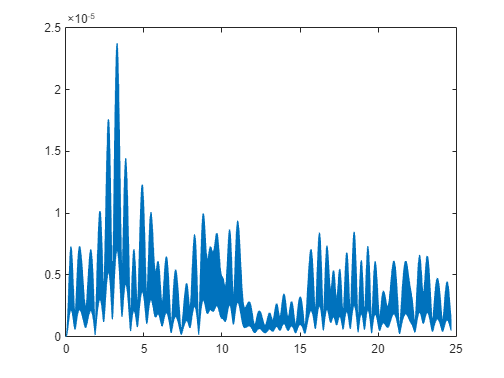

clear detectionSummary dvSummary;

velFig = figure;
detectionSummary = createArray(4,0);
dvSummary =createArray(1,0);

for f=1:numFolders
    clear ekfResult p3pResult

    %% Get current folder
    currentFolder = string(listOfFolderNames(f));
    parts = strsplit(currentFolder, '\');
    trajName = string((parts{end}));

    %% Import data (also run P3P)
    [groundTruth, imuData, p3pResult, simset] = importSimData(currentFolder,diffImuHz, aiding, map);

    %% Preprocess IMU (downsample and calibrate)
    ekfHz = 250;
    [u_hist, u_timeHist] = preprocessImuData(imuData, diffImuHz, down2kHz, downEkf, calibrate, selectedPerturb, simset.accelCalib, simset.gyroCalib, simset.imuHz, ekfHz);

    %% Plot velocity
    speed_gt = vecnorm(groundTruth.quad.state(8:10, :));
    dv = diff(groundTruth.quad.state(8:10, :),1,2);
    dv_mag = vecnorm(dv);
    velAx = plot(groundTruth.quad.time(1, 3:end), dv_mag(:,2:end));
    
    %%Get groundtruth constant velocity phases
    constVel_gt = zeros(1,size(u_hist,2));
    dv_mag_thresh = 1.5*10^(-5);
    for i=1:size(u_hist,2)
        [closestDiff, closestIndex] = min(abs(groundTruth.quad.time(1,:)-u_timeHist(1,i))); %find index of closest time
        if dv_mag(:,closestIndex)<= dv_mag_thresh
            constVel_gt(1,i)=1;
        end
    end

    %% Test velocity detector
    T_w = nan(1,size(u_hist, 2));
    T_a = nan(1,size(u_hist, 2));
    cupt = nan(1,size(u_hist, 2));
    for i=1:size(u_hist, 2)
        [cupt(:,i), T_a(:,i), T_w(:,i)]=constVelDetector(u_hist(:,i), 3*10^(-5), 0.1, 5, i); %guess 3e-5 and 0.08
    end

    %% Evaluate
    y_true = constVel_gt;
    y_pred = cupt;
    TP = sum((y_true == 1) & (y_pred == 1)); % True Positives
    TN = sum((y_true == 0) & (y_pred == 0)); % True Negatives
    FP = sum((y_true == 0) & (y_pred == 1)); % False Positives (predicted positive, actually negative)
    FN = sum((y_true == 1) & (y_pred == 0)); % False Negatives (predicted negative, actually positive)
    FP_percent = FP/size(y_true,2)*100;

    %% Create summary?
    detectionSummary= [detectionSummary, [constVel_gt; cupt; T_a; T_w]];
    dvSummary =[dvSummary, dv_mag];

end

## What do the dv magnitude statistics look like?

%histfit
